clc
close all
clear variables

% calculated in previous problem
Rm = 3;
Req = .25;
% measurements in order Vdc[i]=VRm[i]=fenq[i]
Vdc = [5.2;
    4.79;
    4.33;
    3.75;
    3.29;
    2.81;
    2.25;
    1.75;
    1.21;
    .71;
    .52];
Vout = [.055;
    .05;
    .045;
    .042;
    .039;
    .037;
    .032;
    .03;
    .027;
    .023;
    .021];
fenq = [2010;
    1982;
    1867;
    1627;
    1407;
    1187;
    949;
    725;
    457;
    229;
    147];
% calculations
Idc = Vout/Req;
Vemf = Idc*Rm;
omega = (2*pi/1920).*fenq;
k = (Vdc - Vemf)./omega;
A = [omega ones([11 1])];
Y = k.*Idc;
B_Tint = linsolve(A,Y);

tab = array2table([Vdc Vout fenq Idc k omega],'VariableNames',{'Vdc(V)','Vout(V)','fenq(Hz)','Idc(A)','k','omega'})

tab = 11×6 table
    Vdc(V)    Vout(V)    fenq(Hz)    Idc(A)       k        omega 
    ______    _______    ________    ______    _______    _______

      5.2      0.055       2010       0.22     0.69021     6.5777
     4.79       0.05       1982        0.2       0.646     6.4861
     4.33      0.045       1867       0.18     0.62032     6.1097
     3.75      0.042       1627      0.168     0.60965     5.3243
     3.29      0.039       1407      0.156     0.61289     4.6044
     2.81      0.037       1187      0.148      0.6091     3.8844
     2.25      0.032        949      0.128     0.60085     3.1056
     1.75       0.03        725       0.12     0.58587     2.3726
     1.21      0.027        457      0.108     0.59243     1.4955
     0.71      0.023        229      0.092     0.579

B = B_Tint(1,1)

B = 0.0137

T_int = B_Tint(2,1)

T_int = 0.0389

k_avg = mean(k)

k_avg = 0.6094

k_std = std(k)

k_std = 0.0354

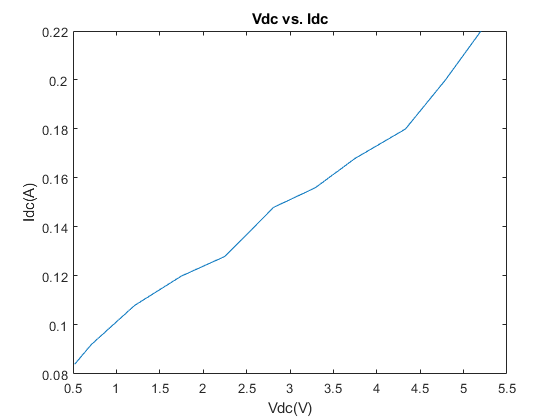


plot(Vdc, Idc)
title('Vdc vs. Idc')
xlabel('Vdc(V)');
ylabel('Idc(A)');

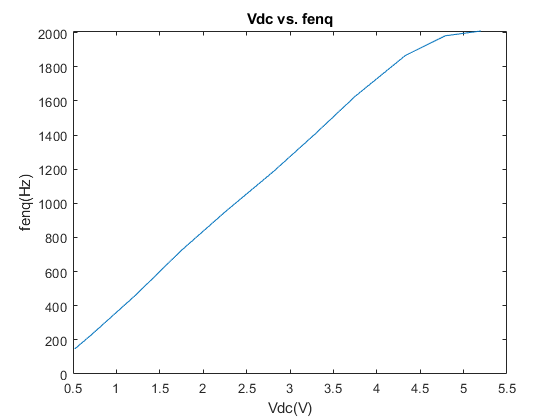

plot(Vdc,fenq)
title('Vdc vs. fenq')
xlabel('Vdc(V)');
ylabel('fenq(Hz)');     

% I = mean(Idc)
% O = mean(omega)
% V = mean(Vdc)


